# **LSM710 Simulated Confocal: Laser Study**

#### **Here, we will model the Zeis LSM710 confocal microscope, studying how laser power can be modified to change the overall FOM.**

In particular, we will show a model setup where alexa 488, 568, and 647 are imaged using the 488/561/647 MBS that come standard with the Zeiss 710.

#### Model Components: 

- Fluorescence Filters: 488/561/647 MBS

- Lasers:  Argon, (488 nm, 25mW) | HeNe (561 nm, 20mW) | HeNe2 (633 nm, 5mW).

- Detectors: 34 channels, 9.8nm wide

- Fluorophore spectra (ThermoFisher) (Alexa 488, 567, 647)

**Importing features**

%I first downloaded a 488/561/647 MBS excel sheet from ? (long time ago)

**Filter**

filterSpectra = readmatrix('/assets/MBSZeiss.csv'); %import filter spectra into matrix

%VISUAL:
scatter(filterSpectra(:,1), filterSpectra(:,2)) 
title("488/561/647 Main Beam Splitter: Transmittance")
ylim([0 1])

**Lasers**

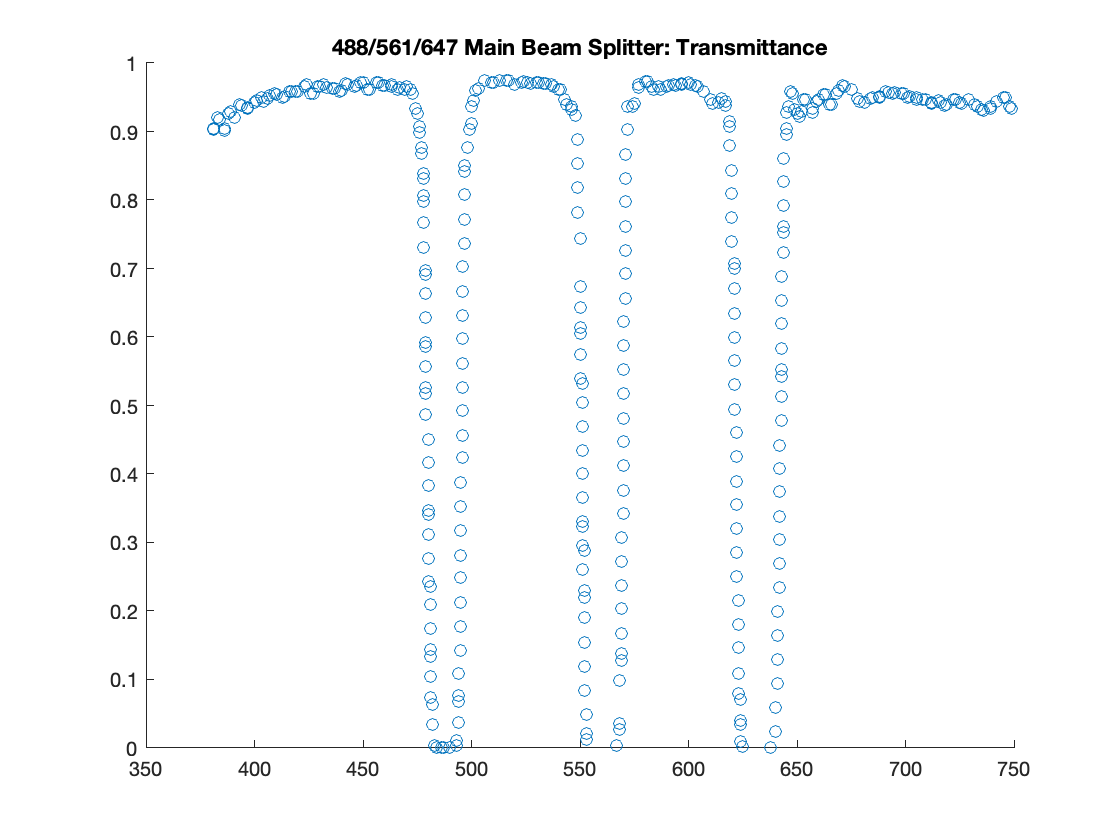

%let's generate these lasers:


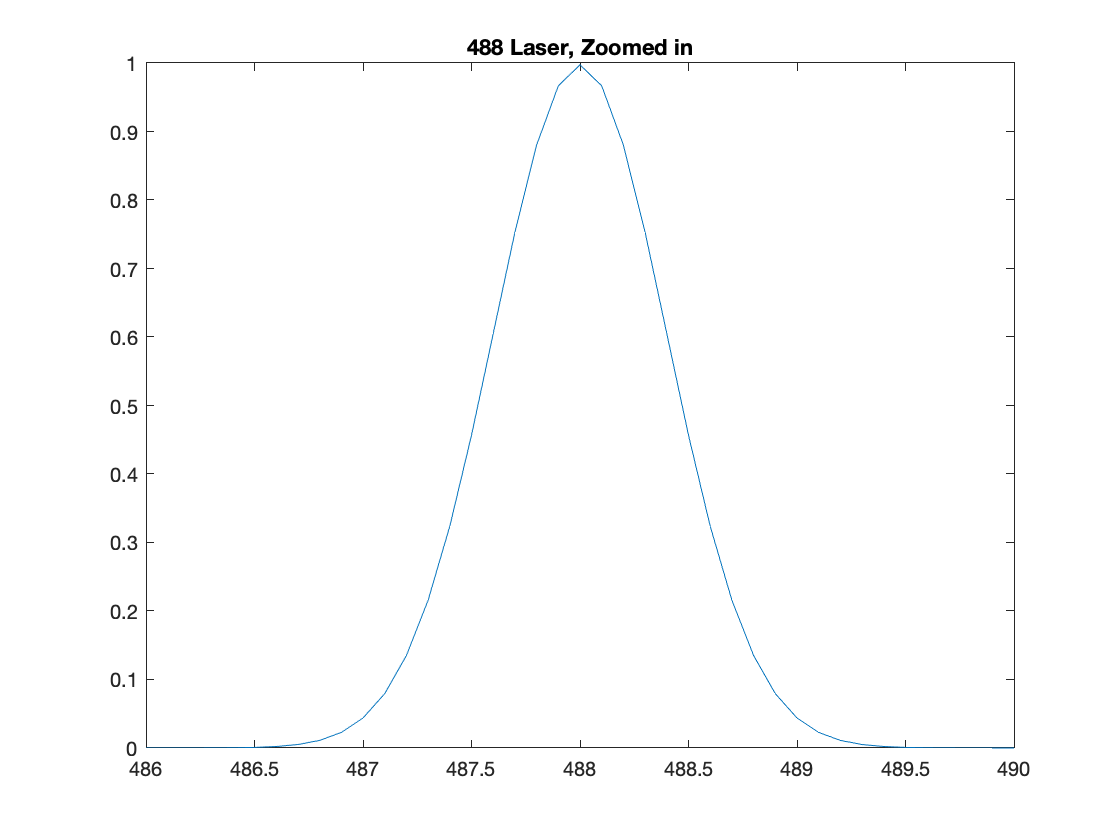

wavelengths = [488 561 633]; %What lasers do we want to use?


lasers = makeLaser(wavelengths); %this function can found as "makeLaser.m" in functions

%what do the lasers look like?
%488 laser looks like:
plot(lasers(:,1,1),lasers(:,2,1))
title('488 Laser, Zoomed in')


plot(lasers(:,1,1),lasers(:,2,1)) %this is the same laser as before

xlim([300 700])                    %just changed the x-range to zoom out.
title('488 laser, Zoomed out')

**Detector**

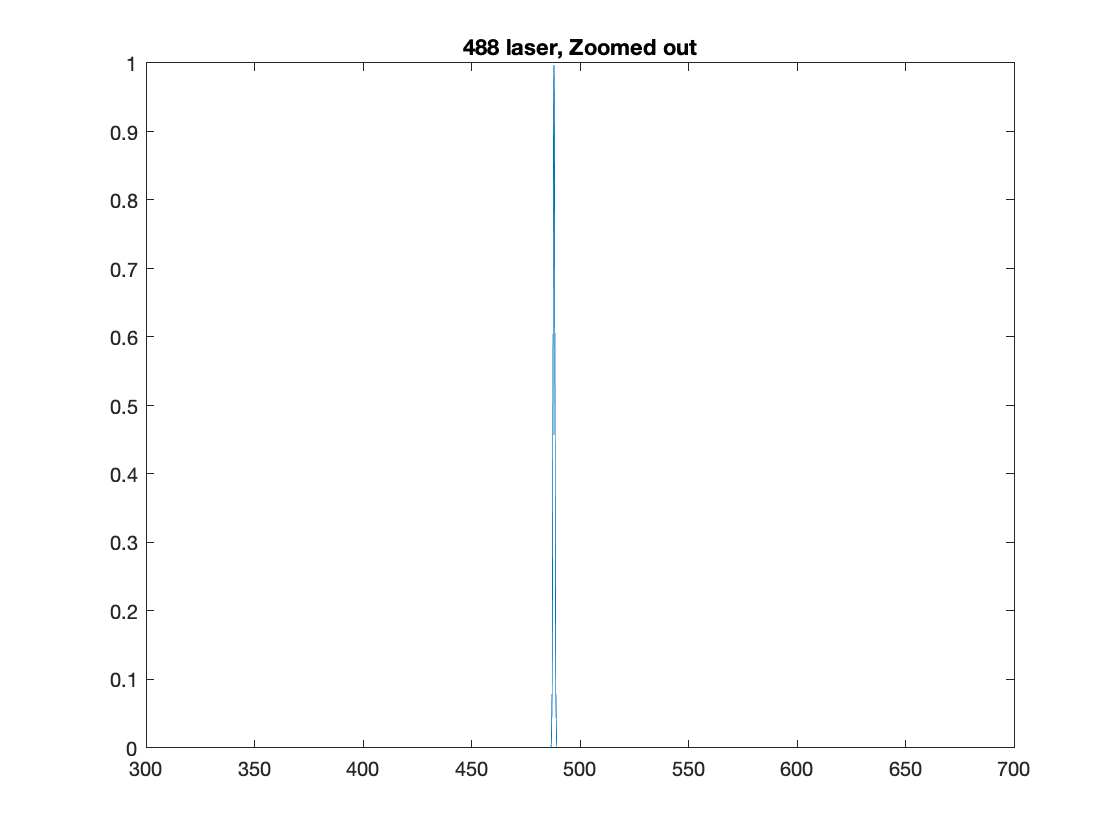

%The detector is just modeled as a 34 channel, 9.8nm wide array. This will
%become more clear later.


detector = 400:9.8:733.2;

%here, 400 is the beginning of channel 1, and 733.2 is the end of channel
%34


**Fluorophores**

%let's iterate through assets and collect our fluorophores

d = dir("assets/Alexa*"); %this pulls all the filenames with "alexa" into a struct

fluors = struct;% I'm going to put my fluorophores in a structure

for k = 1:length(d)                            %iterate through all the alexa fluors I have
    fluors(k).('name') = d(k).name;             %store their name in a structure
    fluors(k).('Spectra') = readmatrix(d(k).name); %then store their spectra in the stucture
end

fluors

fluors = 1×3 struct array with fields:
    name
    Spectra


**All our components are collected. **

**To model this system, we will start with the ****lasers****, which excite the fluorophores according to their excitation spectra. **

**First, we have to combine the lasers and fit them to our detector range.**

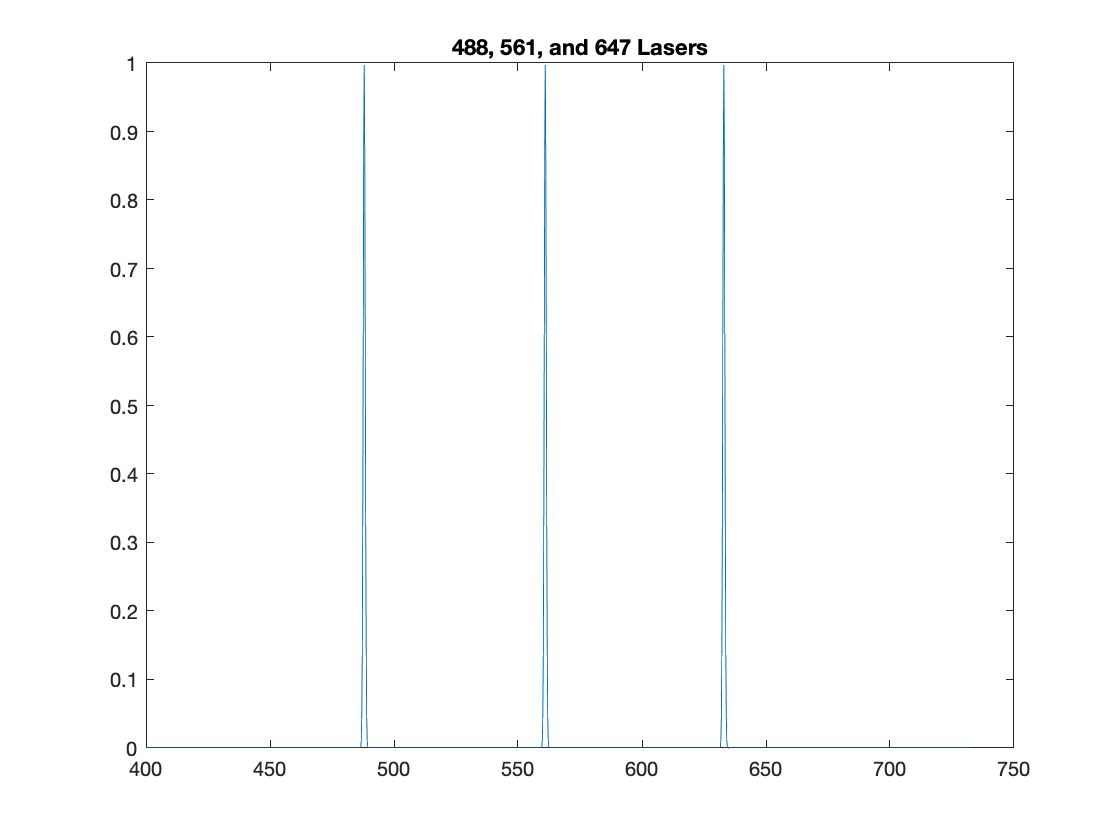

%the lasers are defined at a 0.1 nm resolution. To fit them to our
%detector and fluors, we have to downsample them to a 0.2nm resolution.

fitRange = (400:0.2:733.2)'; %this is our wavelength range for everything to fit to

laser488 = interp1(lasers(:,1,1),lasers(:,2,1),fitRange,"linear","extrap");
laser488(laser488<0) = 0;

laser561 = interp1(lasers(:,1,2),lasers(:,2,2),fitRange,"linear","extrap");
laser561(laser561<0) = 0; 

laser647 = interp1(lasers(:,1,3),lasers(:,2,3),fitRange,"linear","extrap");
laser647(laser647<0) = 0;

%Now the 3 lasers are formatted to one another, we can simply add them
%together:

lasersCombined = laser488 + laser561 + laser647;

%Now we can plot all three on the pertinent range:
l = figure;
plot(fitRange, lasersCombined)
title("488, 561, and 647 Lasers")

**Next, we have to format our fluorophores to fit this range in a similar way**

**I'm going to store the excitation and emission spectra in separate fields for each fluorophore. You'll see in a second**



displayNameEx = ["488 Excitation","561 Excitation", "647 Excitation"]; %these are just labels for the plot
displayNameEm = ["488 Emission", "561 Emission", "647 Emission"];

s = figure;
hold on %just graphing stuff

for k = 1:length(fluors) %This loop will interpolate and extrapolate on the fluorophore spectra, fitting it to our range
    fluors(k).('ex') = interp1(fluors(k).Spectra(:,1),fluors(k).Spectra(:,2),fitRange,"linear","extrap"); %excitation side
    fluors(k).('em') = interp1(fluors(k).Spectra(:,1),fluors(k).Spectra(:,3),fitRange,"linear","extrap"); %emission side
    plot(fitRange, fluors(k).ex,'--','DisplayName', displayNameEx(k))
    plot(fitRange, fluors(k).em, 'DisplayName', displayNameEm(k))
end

fluors

fluors = 1×3 struct array with fields:
    name
    Spectra
    ex
    em


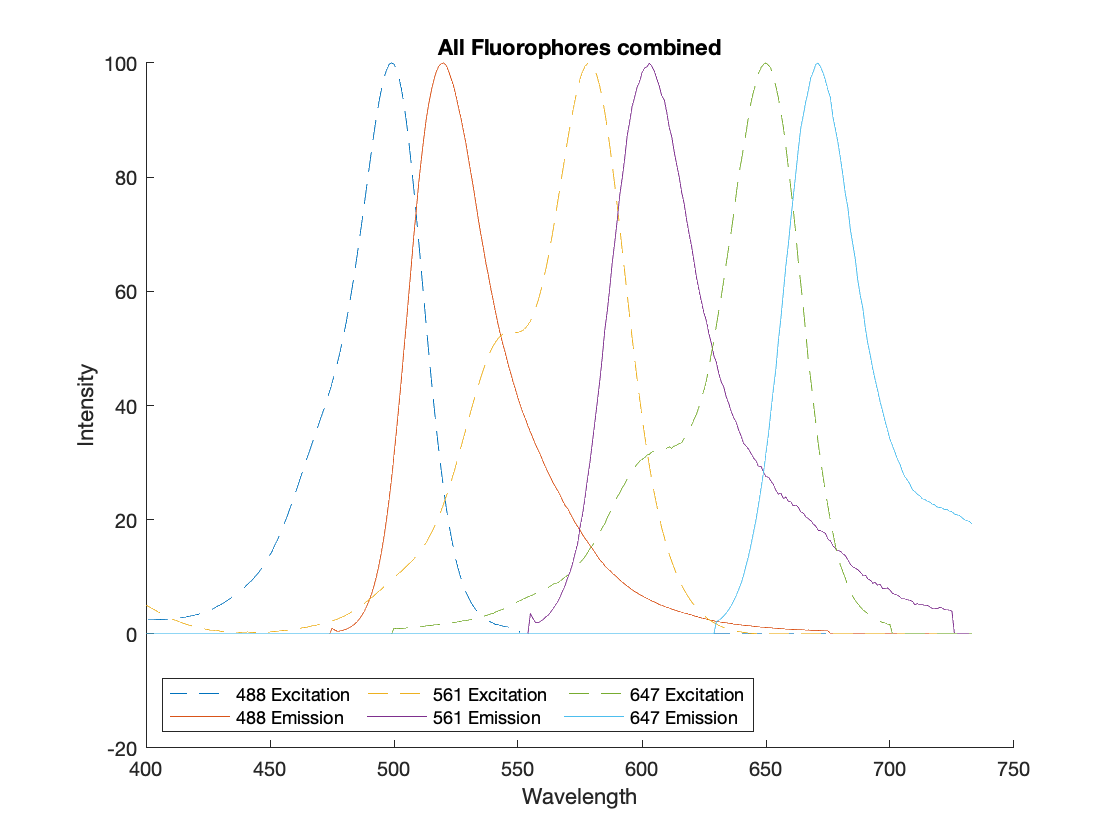


legend('location', 'southwest','NumColumns',3) %more graphing stuff
title("All Fluorophores combined")
ylabel("Intensity")
xlabel("Wavelength")

**Splendid. Lastly, we have to format our filter to the same range.**

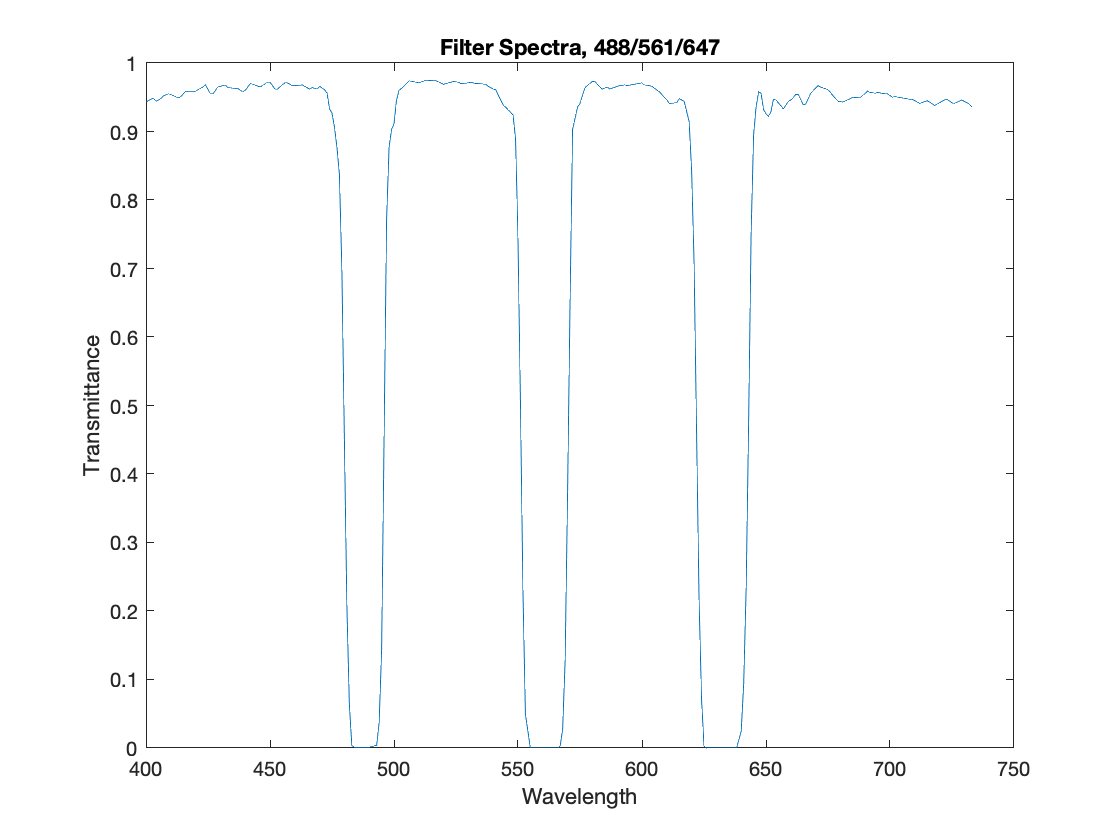

%first we have to clean up the filterSpectra
[c, ia, ic] = unique(filterSpectra(:,1)); %this just removes duplicate values in the filter spectrum
filterSpectraClean = filterSpectra(ia,:); %this stores those clean values in a variable

fitfilterSpectra = interp1(filterSpectraClean(:,1),filterSpectraClean(:,2),fitRange,"linear", "extrap"); %this is fitting the filter spectrum to our range
fitfilterSpectra(fitfilterSpectra<0) = 0;
figure
plot(fitRange, fitfilterSpectra)
title("Filter Spectra, 488/561/647")
xlabel("Wavelength")
ylabel("Transmittance")

**Now that all our components are fitted together, we can start to model. **

**Here, we ask, "What is the FOM when these lasers are unmixed in varying degrees of difficulty?"**

**We start with the lasers exciting each fluorophore**

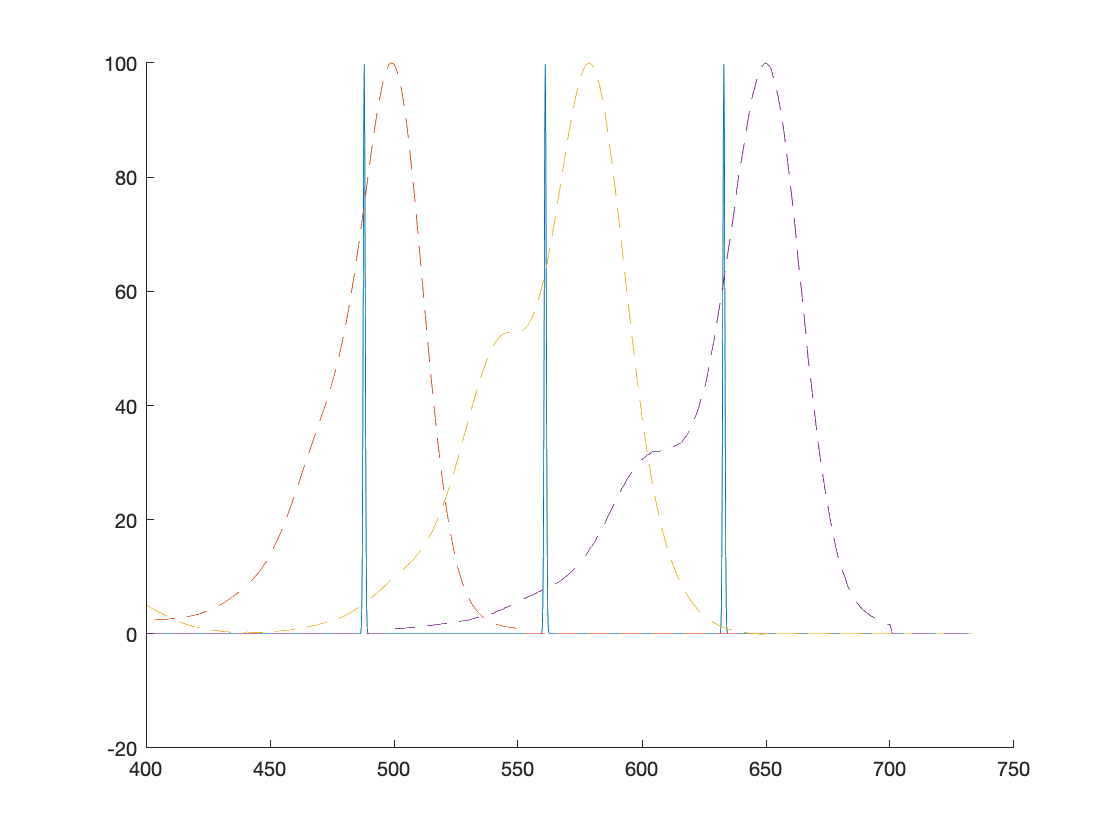

figure
hold on
plot(fitRange,lasersCombined*100)

for k = 1:length(fluors)
    plot(fitRange,fluors(k).ex, '--')
end


laserIntensity = [1 1 1]; % this is the controllable laser intensity (0-100%)
defaultPower = [25 20 5]; % these are the laser powers in mW %Zeiss
EC = [73 88 270];         % Extinction Coefficients - ThermoFisher
qy = [0.92 0.69 0.33];    % Quantum Yield - ThermoFisher


exFactor = zeros(1,3); %array creation

%This loop is what tells us: How much will the lasers excite each
%fluorophore according to their position? This is not an absolute number,
%but relative to one another

%%%%%%%%%%%%%%%%%%%
for k = 1:length(fluors)
    exFactor(k) = sum(fluors(k).ex.*lasersCombined); % This multiplies the lasers by each spectra
end
%%%%%%%%%%%%%%%%%%%

scaledexFactor = exFactor/(max(exFactor)); % the excitation factor is stored as single, relative values

%now we can assess the relative brightness of each fluorophore to find the
%optimal laser power:

relativeBrightness = laserIntensity.*defaultPower.*EC.*qy.*scaledexFactor/100 %we just multiply all the scalars

relativeBrightness =    16.7900   11.2839    4.1470



%where do we go from here? we want to find the optimal laser power that
%normalizes the brightness for each fluorophore. In this case, we'll have
%to lower the 488 and 561 laser. 

optimizedIntensities = laserIntensity./(relativeBrightness/min(relativeBrightness)) %this just uses the dimmest to scale the laser powers

optimizedIntensities =     0.2470    0.3675    1.0000



%this is a good starting point, but we'll need to refine this for unmixing.

**After we shoot our lasers at the fluorophores, they should all have the same brightness, giving us the spectra we started with**

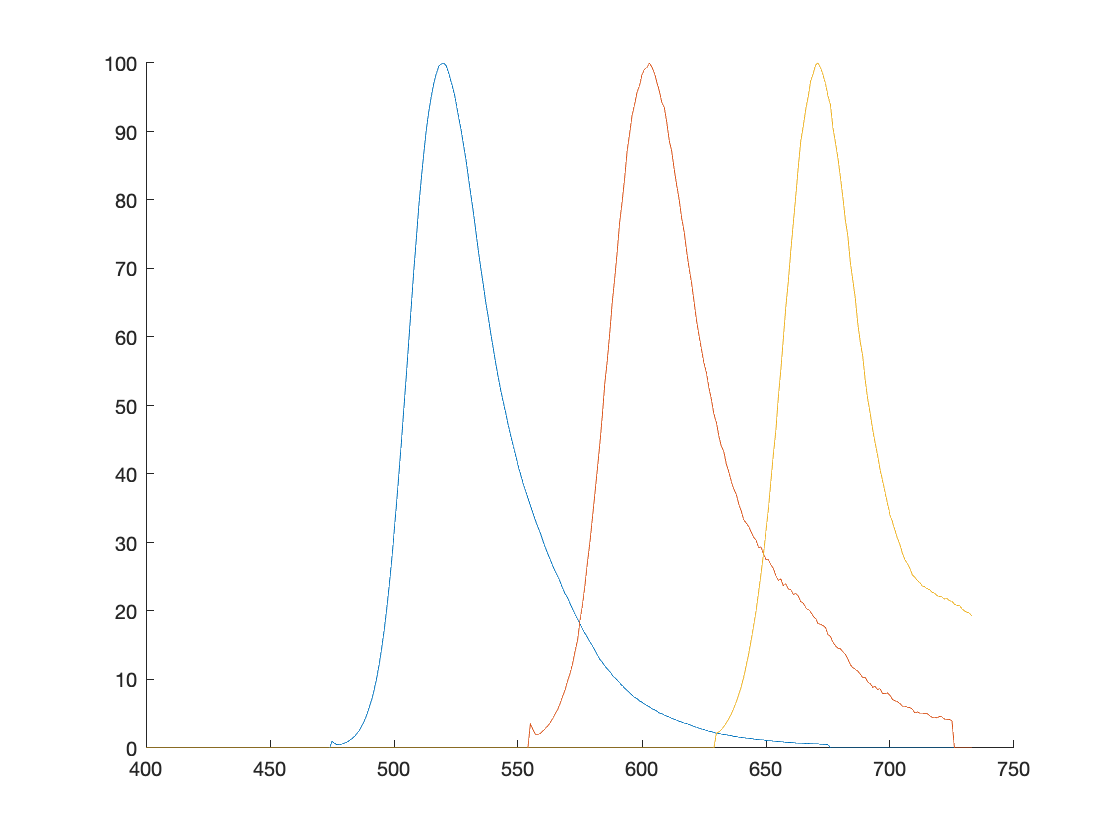

figure
hold on
for k = 1:length(fluors)
    plot(fitRange, fluors(k).em)
end

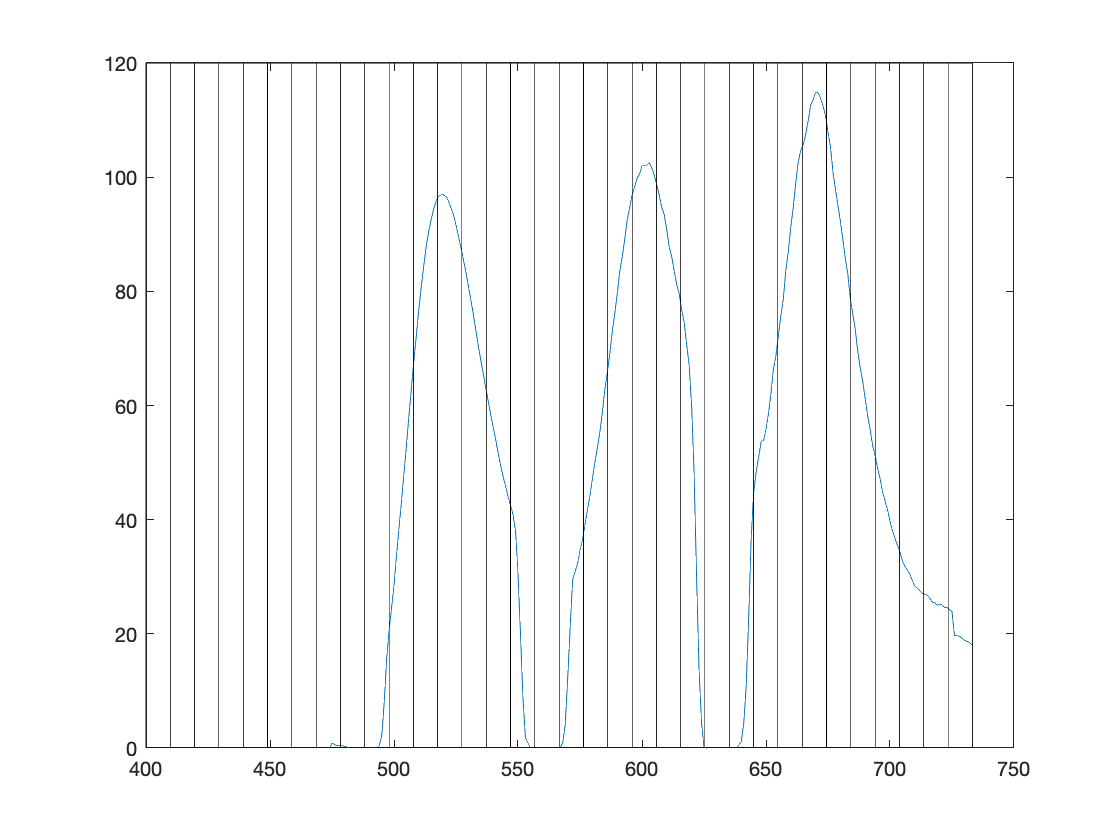


%this light will be emitted and pass through the 488/561/647 filter. What
%will that look like?

fluorsCombined = fluors(1).em + fluors(2).em + fluors(3).em; %this is just combining all fluors into the same pixel
figure
postFilterSpectra = fitfilterSpectra.*fluorsCombined; %this is what the spectra look like when passed through the filter
plot(fitRange,postFilterSpectra)

f = [ 1 2 3 4];
%Now that spectra is sampled by the spectral detector, like so: (this is
%just a graph, not actually doing anything mathematical here
for k = 1:(length(detector)-1)
    first = detector(k);
    last = detector(k+1);
    v = [first 0;last 0; last 120; first 120];
    patch('Faces', f, 'Vertices', v, 'FaceColor','none')
end

hold off

**As a result of spectral imaging, we will obtain the following:**

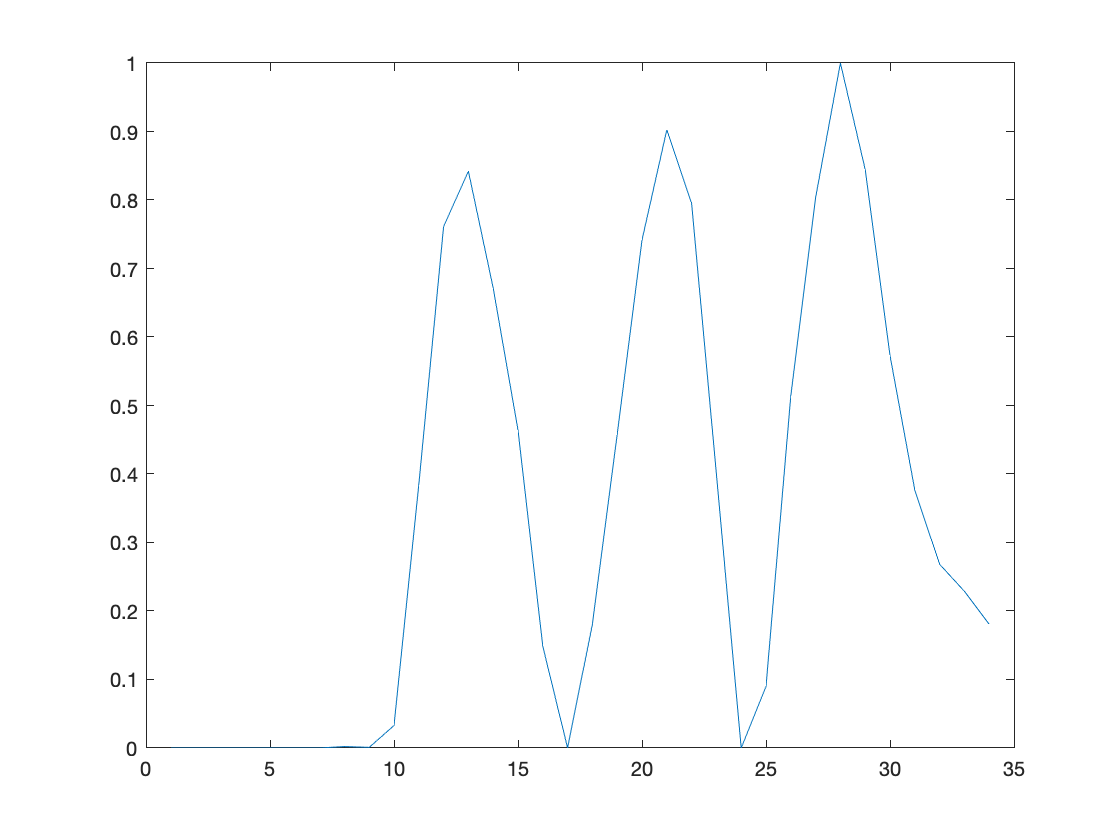

%here's where we actually spectrally image the postFilterSpectra.
channelVal = zeros(34,1);
i = 1;
for k = 1:49:(length(fitRange)-49) %I'm iterating through the wavelength domain. 0.2nm resolution, 9.8nm distance = 49
    channelVal(i) = trapz(postFilterSpectra(k:k+49)); %this takes the integral of this bandwidth as a psuedo photon number
    i = i + 1;
end

plot(rescale(channelVal))

%what do our fluourophore standards look like, when each imaged with the
%same settings?

fluorStandard = zeros(3,34);
i = 1;


for k = 1:length(fluors)
    fluors(k).('postfilter') = fluors(k).em.*fitfilterSpectra;
end

for j = 1:length(fluors) %for each fluorophore
    for k = 1:49:(length(fitRange)-49) %iterate through the domain
        fluorStandard(j,i) = trapz(fluors(j).postfilter(k:k+49)); %this takes the integral of this bandwidth as a psuedo photon number
        i = i + 1;
    end
    i = 1;
end


titles = ["488 Standard","568 Standard", "647 Standard"]

titles = 1×3 string array
    "488 Standard"    "568 Standard"    "647 Standard"


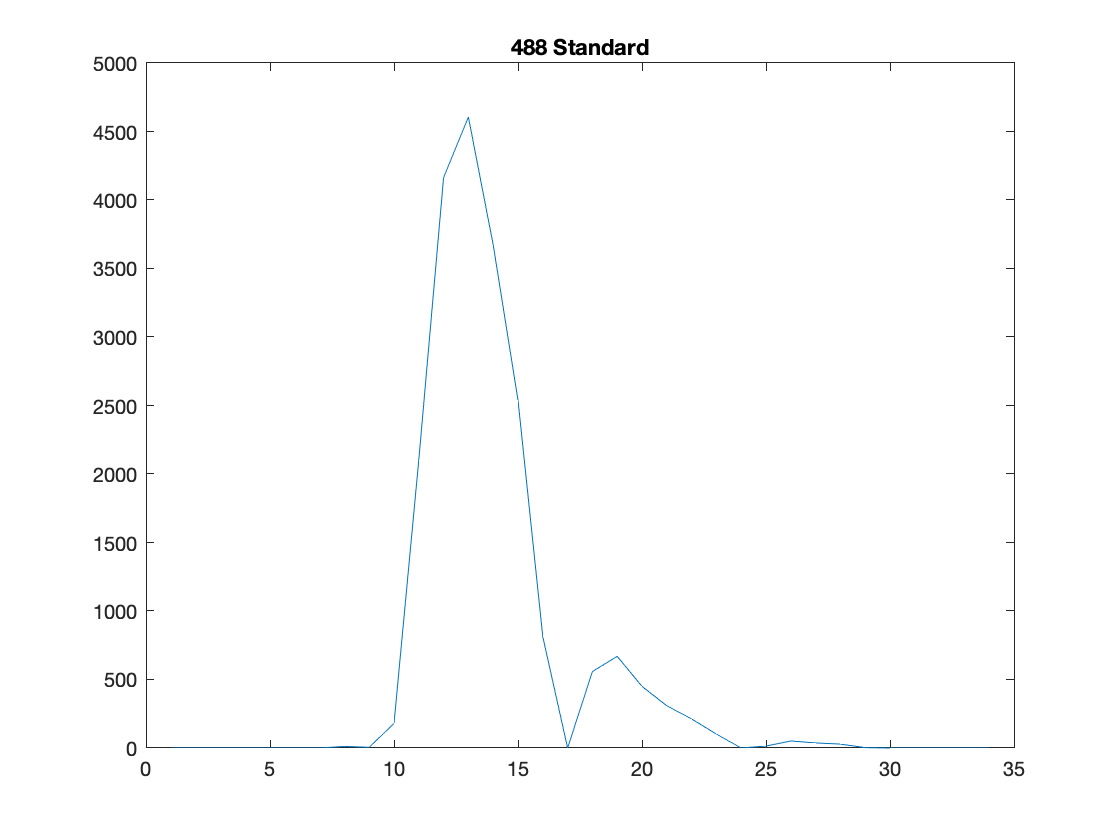

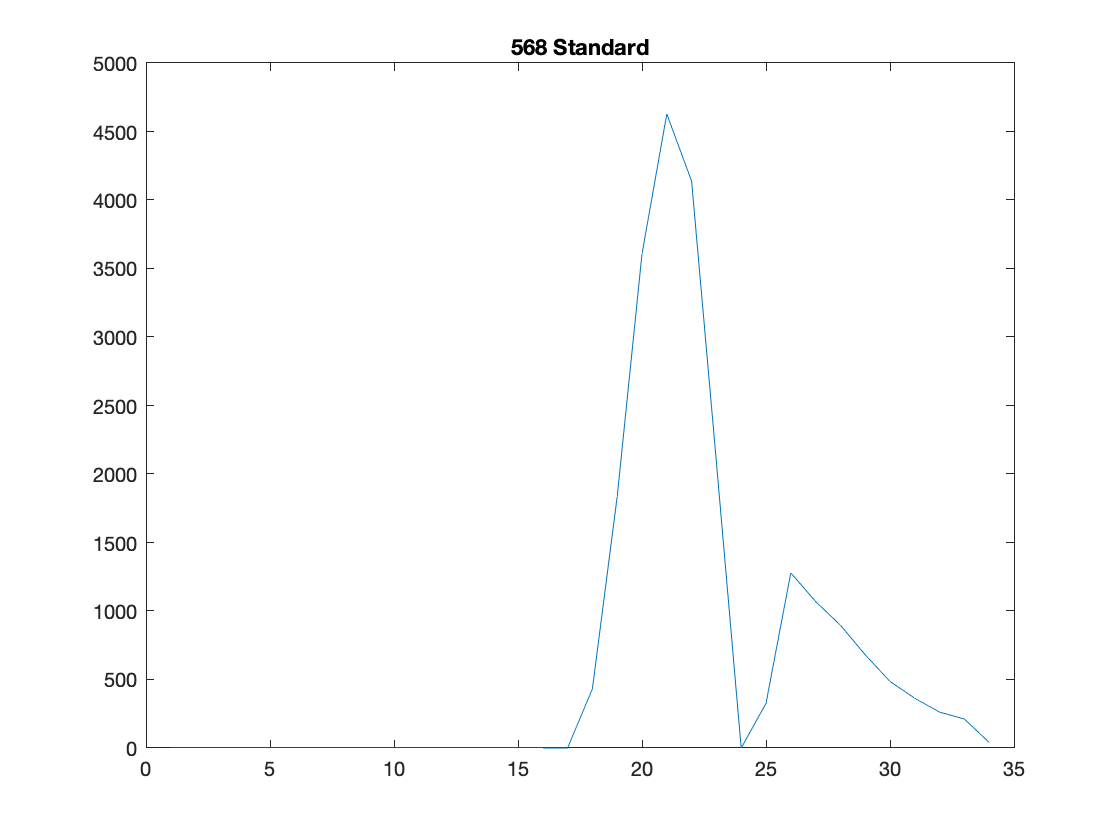

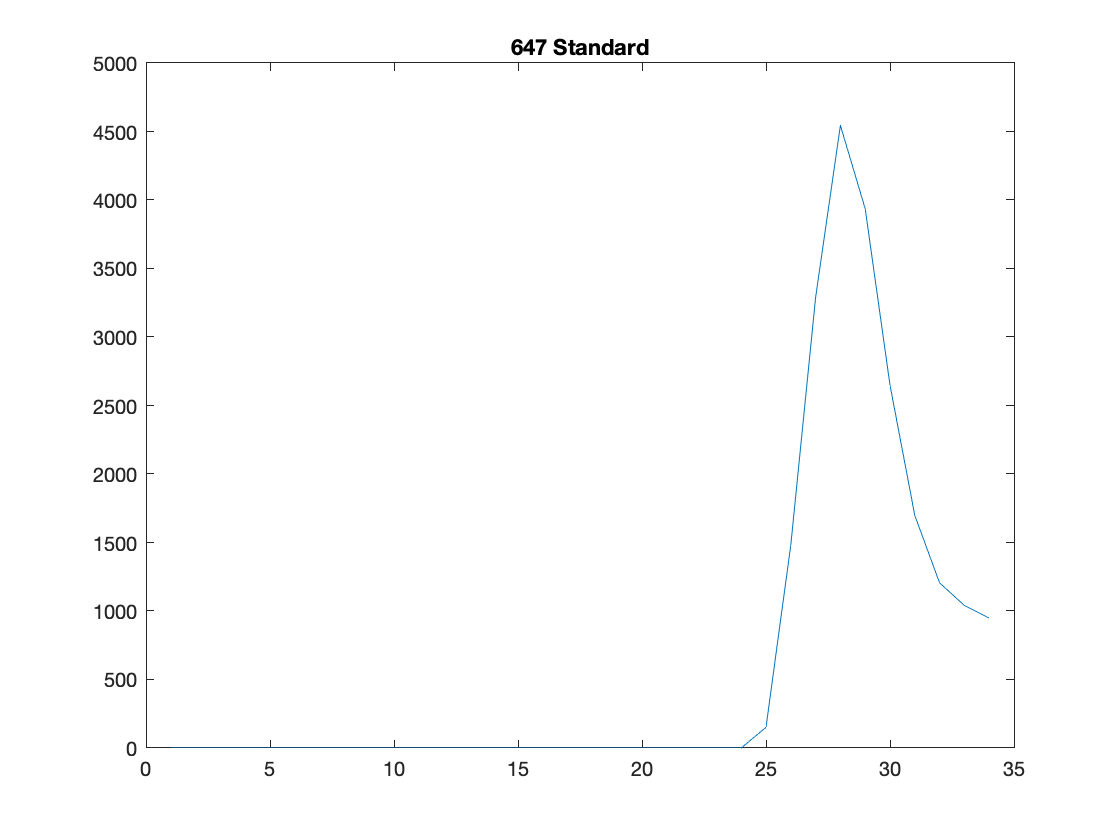


for k = 1:3 %this is just plotting each of those fluorophores.
    figure
    plot(fluorStandard(k,:))
    title(titles(k))
end

Thus Linear unmixing of the combined image produces the following:

lsqnonneg(fluorStandard', channelVal)

ans =     1.0000
    1.0000
    1.0000


This is of course, without any noise. When we add noise to the emission spectrum, run it through our filter, spectrally image, and unmix it again, we obtain the following:

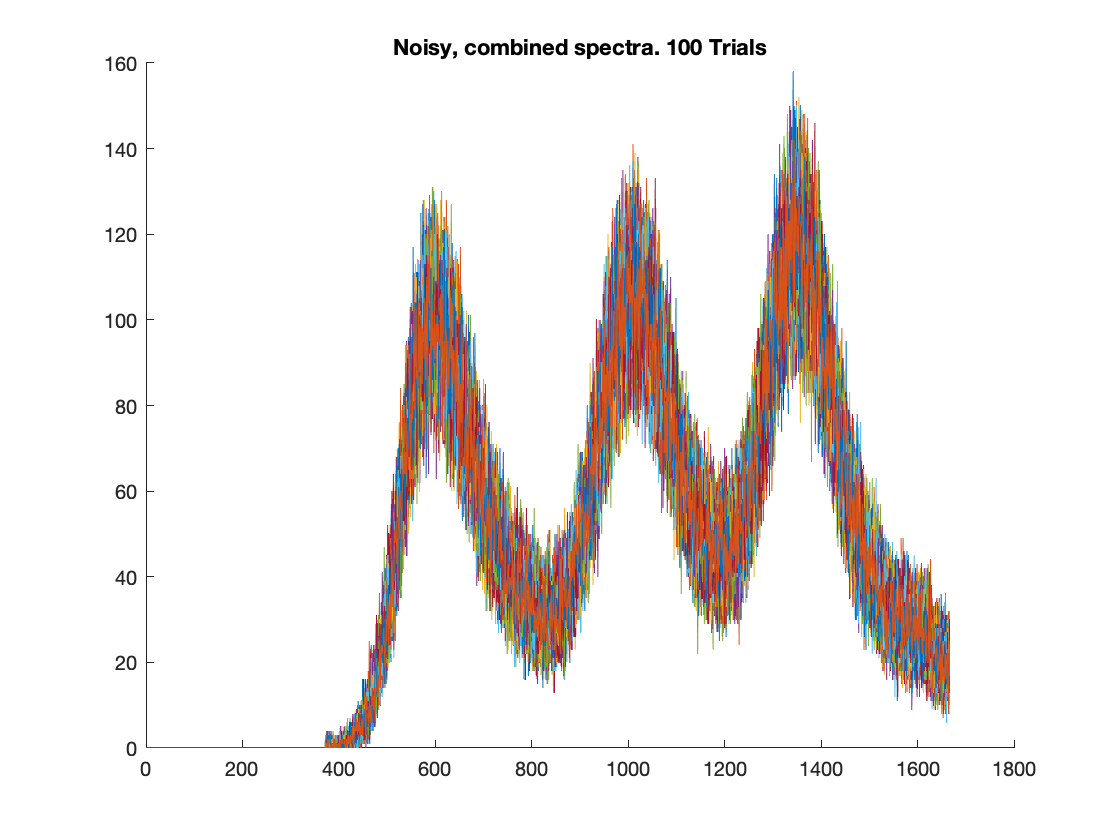

B = repmat(fluorsCombined,1, 1000); %this is a step to basically make our combinedFluorophore spectrum into a really big image
B = imnoise(B*1e-12, 'poisson')*1e12; %this function then applies poisson noise to the entire image

figure
hold on
for k = 1:100
    plot(B(:,k)) %this plots 100 different noisy versions of the combined spectra.
end
title("Noisy, combined spectra. 100 Trials")

%Now we can run them all through our filter:

Bfiltered = B.*fitfilterSpectra;
%Now we can spectrally sample, and linearly unmix each one:
sampledB = zeros(34, 1000);
unmixedB = zeros(3, 1000);

%% The following loop is probably the most complicated in the program. 
i = 1;
for k = 1:size(B,2) %this iterates through our Large matrix of the noisy, combined fluors.
    for j = 1:49:length(fitRange)-49 %this iterates through the domain of each, singular "image"
        sampledB(i,k) = trapz(Bfiltered(j:j+49,k)); %This tells us, "how many photons did we capture from channel 10," etc.
        i = i + 1;
    end
    i = 1;
    unmixedB(:,k) = lsqnonneg(fluorStandard', sampledB(:,k)); %this unmixes every thing
end

FOMS = mean(unmixedB,2)

FOMS =     1.0000
    1.0003
    0.9996


Elapsed time is 4.992710 seconds.
